## **Ajuste mediante modelos de primer orden**

En la siguiente sección se desarrolla un ejemplo usando los 3 diferentes métodos de ajuste de modelo de primer orden.

Se genera un modelo de segundo orden especificando los ceros, polos, ganancia y retardo del sistema mediante la función [zpk](https://www.mathworks.com/help/control/ref/zpk.html). El sistema que elegimos para el ejemplo no tiene ceros, tiene dos polos (-1.8 y -2.2), tiene una ganancia de 1.24 y un retardo de 0.89 segundos.

%creación de un modelo de segundo orden
G=zpk([],[-1.8 -2.2],1.24,'InputDelay',0.89)

G =
 
                      1.24
  exp(-0.89*s) * ---------------
                 (s+1.8) (s+2.2)
 
Continuous-time zero/pole/gain model.



%generación de la respuesta temporal
figure(1)
clf
step(G);%comprobamos que el sistema se estabiliza

[y,t]=step(G,[0:0.01:6]);%recolectamos los datos a nuestro gusto
inicio=find(y>0,1)%identificamos el dato a partir del cual el modelo responde a la entrada

inicio = 91


yvals=y(inicio:end);%valores útiles de y
tvals=t(inicio:end);%valores útiles de t
k=yvals(end)-y(1);%valor de k según la fórmula

*Método de regresión*

[p,s] = polyfit(tvals,log(1-yvals/(k+eps)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tf_est = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tf_est =
 
                    0.313
  exp(-1.44*s) * ------------
                 0.5551 s + 1
 
Continuous-time transfer function.



*Método gráfico*

tau2=t(inicio);%primer valor donde y reacciona a la entrada
valT=find(y>0.632*y(end),1);%posición donde y alcanza el 63.2% de su valor final
T2=t(valT)-tau2;%valor de T por definición
tf_est2=tf(k,[T2 1],'InputDelay',tau2)%función de transferencia resultante

tf_est2 =
 
                  0.313
  exp(-0.9*s) * ----------
                1.08 s + 1
 
Continuous-time transfer function.



***Comparación entre métodos***

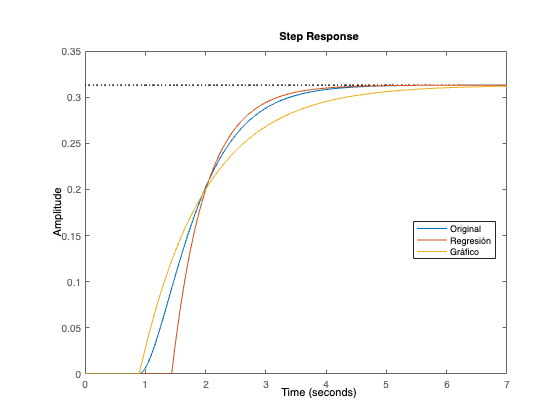

figure(1)
hold on
step(tf_est)
step(tf_est2)
legend({'Original','Regresión','Gráfico'},'Location','best')

## **Ajuste mediante modelos de primer orden**

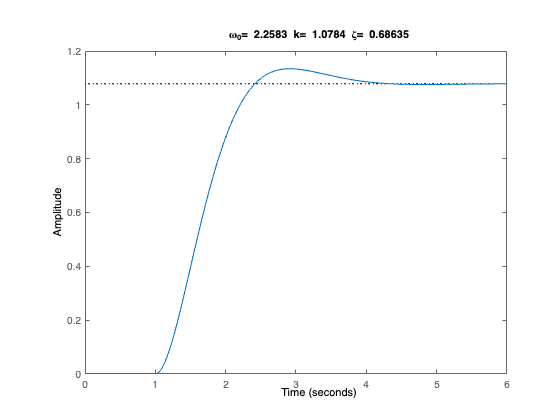

a =5.5;
b =3.1;
c =5.1;
tau =1;
tf1 = tf(a,[1 b c],'InputDelay',tau);%función de transferencia a partir de los datos
figure(1)
clf
step(tf1);
title(["\omega_0= "+sqrt(c)+" k= "+a/c+" \zeta= "+b/(2*sqrt(c))])%cálculo de valores de los parámetros


[y,t] = step(tf1);%recolección de datos por recomendación de MatLab
inicio = find(y>0,1);%dato a partir del cual el sistema reacciona
tau = t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 1.0102

deltaY = y(end)-y(1)%delta de y por definición

deltaY = 1.0760

Mp = max(y)-y(end);%sobreimpulso máximo pode definición
Tp = t(y==max(y))-tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.6715

omega0 = pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 2.2295

tf_est = tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tf_est =
 
                         5.348
  exp(-1.01*s) * ---------------------
                 s^2 + 2.994 s + 4.971
 
Continuous-time transfer function.



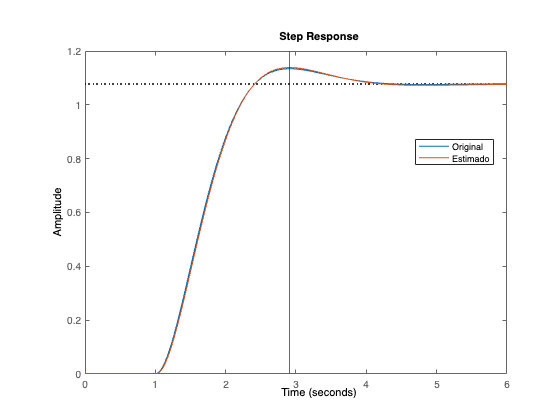

figure(2)
clf
step(tf1)
hold on
step(tf_est)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')